clear variables
close all

## 41058 Minor Project 2:

## Modelling and Control of a Practical Dynamic System (Coupled Tanks System)

This file is a template for your assignment submission. The assignment is organized in** 5 Tasks**, each containing different parts. The marks breakdown is shown throughout the document and you will be prompted to enter details for your answers as necessary. Please ***do not change*** ***any of the variable names, ***only their values where you are prompted by 'Students are required to input below:'. 

Please fill in your student details below:

a_student_id = '24439287';
a_student_first_name = 'Tamsyn';
a_student_last_name = 'Crangle';

b_student_id = '123456789';
b_student_first_name = 'Arya';
b_student_last_name = 'Nooralizadeh Asl';

c_student_id = '123456789';
c_student_first_name = 'Dyandra';
c_student_last_name = 'Prins';

d_student_id = '123456789';
d_student_first_name = 'Amadee';
d_student_last_name = 'Thotawatta';

# Task 1 [3 marks]

Define the inputs and outputs of the 3 key system components, clearly labelling the inputs and outputs, including units. 

**Marks breakdown [3 marks]:**

-  Correct Sensor 2 input/output and units

-  Correct Valve 1 input/output and units

-  Correct Coupled tanks input/output and units

Students are required to input below:

## Sensor 2:

    input_units_sensor_2 = 'mm';
    input_label_sensor_2 = 'Level';
    output_units_sensor_2 = 'A';
    output_label_sensor_2 = 'Current?';
    component_label_sensor_2 = 'Sensor 2';

## Valve 1:

    input_units_valve_1 = 'L/min';
    input_label_valve_1 = 'Flow Rate';
    output_units_valve_1 = '%';
    output_label_valve_1 = 'Value Position';
    component_label_valve_1 = 'Valve 1';

##  Coupled Tanks:

    input_units_coupled_tanks = 'L/min';
    input_label_coupled_tanks= 'Coupled Input';
    output_units_coupled_tanks = 'L/min';
    output_label_coupled_tanks = 'Coupled Output';
    component_label_coupled_tanks = 'Coupled Tanks';


Do not change the lines below:

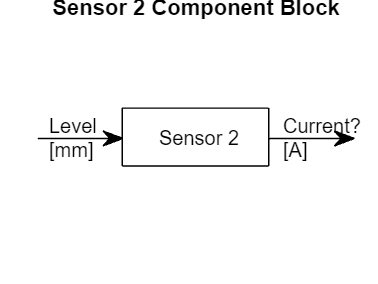

    % Sensor 2:
    figure(1);
    plot([-10 10 10 -10 -10],[-2.5 -2.5 2.5 2.5 -2.5],'color', 'k')
    axis([-20 20 -10 10])
    title('Sensor 2 Component Block')
    annotation('arrow',[0.1 0.325],[0.5125 0.5125])
    annotation('arrow',[0.7125 0.9375],[0.5125 0.5125])
    axis off

    text(-5, 0, component_label_sensor_2);
    text(-20, 1, input_label_sensor_2);
    text(-20, -1, "[" + input_units_sensor_2 + "]");
    text(12, 1, output_label_sensor_2);
    text(12, -1, "[" + output_units_sensor_2 + "]");

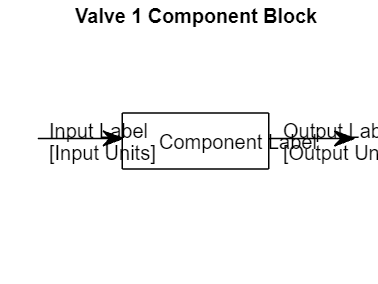

    
    % Valve 1:
    figure(2)
    plot([-10 10 10 -10 -10],[-2.5 -2.5 2.5 2.5 -2.5],'color', 'k')
    axis([-20 20 -10 10])
    title('Valve 1 Component Block')
    annotation('arrow',[0.1 0.325],[0.5125 0.5125])
    annotation('arrow',[0.7125 0.9375],[0.5125 0.5125])
    axis off

    text(-5, 0, component_label_valve_1);
    text(-20, 1, input_label_valve_1);
    text(-20, -1, "[" + input_units_valve_1 + "]");
    text(12, 1, output_label_valve_1);
    text(12, -1, "[" + output_units_valve_1 + "]");

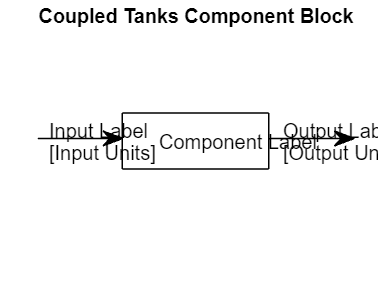

    
    % Coupled Tanks:
    figure(3)
    plot([-10 10 10 -10 -10],[-2.5 -2.5 2.5 2.5 -2.5],'color', 'k')
    axis([-20 20 -10 10])
    title('Coupled Tanks Component Block')
    annotation('arrow',[0.1 0.325],[0.5125 0.5125])
    annotation('arrow',[0.7125 0.9375],[0.5125 0.5125])
    axis off

    text(-5, 0, component_label_coupled_tanks);
    text(-20, 1, input_label_coupled_tanks);
    text(-20, -1, "[" + input_units_coupled_tanks + "]");
    text(12, 1, output_label_coupled_tanks);
    text(12, -1, "[" + output_units_coupled_tanks + "]");

# Task 2 [8 marks]

Please note that you have to fufil 4 parts in this task. 

**Marks breakdown [4 marks]:**

- Deriving coupled tanks transfer function from dynamic equations

- Proposing a method to derive $k_2$

## Coupled Tanks 

Develop the transfer function of the coupled tanks, combine and simplify the tank dynamic equations to obtain:


$$H_{2}(s) = \frac{M(s)+N(s)}{k_{2}T_{1}T_{2}s^{2} + k_{2}(T_{1}+T_{2})s + k_{2}} = \frac{M(s)+N(s)}{Js^{2} + as +k_{2}}$$


Upload images of your full working out (insert>image in the tabs above), ***or*** add a series of Latex Equations here in the live script (Ctrl+Shift+L)

*Example of starting to write Latex Equations...*

Tank 1 Equation: $M(t) + N(t) - X_{1}(t) = A_{1}\frac{\textit{d}H_{1}}{\textit{d}t}$

Tank 2 Equation: $X_{1}(t) - X_{2}(t) = A_{2}\frac{\textit{d}H_{2}}{\textit{d}t}$

------------------------------------------------------------------------------------

***Insert image/s here***

------------------------------------------------------------------------------------

## Find $k_2$

Using the equations you know for second-order systems, can you propose a method to find the value of $k_2$ experimentally?

Upload images of your full working out (insert>image in the tabs above), ***or*** add a series of Latex Equations here in the live script (Ctrl+Shift+L)

------------------------------------------------------------------------------------

***Insert image/s here***

------------------------------------------------------------------------------------

## **Experiment Data**

Obtain the open loop response from the coupled tanks system, save the file as a .csv extension to import data into MATLAB.

**Marks breakdown [2 marks]:**

- Correct open loop response graph

- Correct axes labels and graph title on open loop response graph

- Correct annotations for $\Delta$M and $\Delta H_{2}$ on open loop response graph

Students are required to input below:

    filename = 'CoupledTanks_24439287.xlsx'; % change this to reflect the name of your file - remember to add this file to the MATLAB path or copy the file to the current folder
    

## Data Check

Before performing your analysis, your data should be appropriately truncated and some measure given to ensure that the data is indeed appropriate for analysis. To ensure the data is appropraite for analysis we will be generating a regression model that attempts to find a 'best fit' for the following function:


$$y(t) = a(1- e^{\frac{-bt}{2}})$$


This model will optimise the 'a' and 'b' variables in the aforementioned function until the error between the output function and the data is minimised. Consult a text book on Regression Analysis for more information. If the data you've gathered is appropriate for analysis, then the regression model generated will be a 'good fit'. Goodness of fit can be determined by several metrics, however, we will be using the R-squared value.

Ensure that **R-squared > 0.99** before proceeding with your analysis. Also visually inspect the similarities in the graph generated from the code below and use your judgement to determine if the regression model is a good approximation of your data.

Do not change the lines below:

    % readtable will import the data from your .csv file and store it in an a table
    warning('off','MATLAB:table:ModifiedAndSavedVarnames'); % Turns off warning you'll get as matlab will rename some variables on import.
    ctdata = readtable(filename);
    
    x = ctdata.Timestamp_s_;
    y = ctdata.Tank2Level_mm_;   % If you've named your data something different, just ensure it matches the name given here.
    
    % Prepares data for the fit function
    [xData, yData] = prepareCurveData( x, y );

    % Set up fittype and options.
    ft = fittype( 'a*(1-exp(-b*x/2))', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [150 0.06];
    
    % Fit model to data, i.e. do regression.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Generate y values of the regression model for plotting
    y_1 = @(x) fitresult.a*(1-exp(-fitresult.b*x/2));
    y1 = y_1(x);
    
    % Track the max value to dynamically scale the plot dependant on the data
    if max(y)>max(y1)
        y_lim = max(y)+20;
    else
        y_lim = max(y1)+20;
    end
    
    % Plot both your original data and the regression model. Is it a good fit?
    figure(4)
    plot(x,y,'o','MarkerIndices',1:400:length(y));
    hold on;
    plot(x,y1);
    legend('data','model','Location','northwest');
    ylim([0 y_lim]);
    xlabel('Time [s]')
    ylabel('Tank 2 Level [mm]');
    plottitle = ['R-squared value: ', num2str(gof.rsquare)];
    title(plottitle);
    hold off
    

Determine your Tank 2 maximum and minimum values, as well as your Flow Rate maximum and minimum values.

**For Tank 2 levels** you will either have a plot that visibly comes to steady-state or you might have had to truncate your data to ensure the data you're analysing is in the linear operating region for the system. Depending on the data you acquired you now have a choice, you can: 

- Use the steady-state value as it appears in your data, or 

- Evaluate the limit of the regression model and assume this is the steady-state value.

**For the flow rate into tank 1** you need to pick appropriate values for the maximum and minimum. It is recommended to use **an average maximum and minimum** since the data has not been filtered. **Please use Matlab commands** to derive the required variables and refrain from simply writing a numerical value.

Students are required to input below:

    % change the following lines to generate a plot title and axes labels for the open loop response of the coupled tanks
    plot_title = 'Title: ';  % Input a relvant tile for the plot, by replacing 'Title: '                                
    y_label_left = 'Left Label';                            
    y_label_right = 'Right Label';
    x_label = 'X Label';
    
    % Choose appropriate values for H2 and Flow1 maximum and minimum.
    % These variables can be used later to calculate detla H2 and delta M.
    H2_min = 0;
    H2_max = 100;
    
    Flow1_min = 1;
    Flow1_max = 2.35;
    
    % Select an appropriate time limit for the plot below
    % If the data you acquired gets to steady state, max(ctdata.Timestamp_s_) might be appropriate
    % Else just pick a time to plot that shows your regression model approaching its asymptote (1200 is a good
    % guess, but you might have to edit this).
    timeLimit = 1200;
    
    % Note: for the arrows annotating delta H2 and delta M, you may have to edit the offset values below:
    % offsets for annotations alignment 
    yOffsetStartH2 = 0.1125;     % start of delta H2 arrow (lower value) - this value is added to the H2_min variable
    yOffsetEndH2 = 0.05;         % end of delta H2 arrow (upper value) - this value is subtracted from the H2_max variable
    yOffsetStartValve = 0.035;   % start of delta M arrow (lower value) - this value is added to the Flow1_min variable
    yOffsetEndValve = 0.065;     % end of delta M arrow (upper value) - this value is subtracted from the Flow1_max variable

Do not change the lines below: 

    % annotations for delta H2 (double arrow start and end points)
    yStartH2 = H2_min;
    yEndH2 = H2_max;
    
    % annotations for delta M (double arrow start and end points)
    yStartValve = Flow1_min;
    yEndValve = Flow1_max;
       
    % import the relevant variables from the .csv file in your saved directory  
    datatime = ctdata.Timestamp_s_;                % read in time
    tank_2_level = ctdata.Tank2Level_mm_;      % read in the tank 2 water level data
    valve_1_flow = ctdata.Flow1_L_min_;            % read in the valve 1 flowrate data
    time = 1:1:timeLimit;
    
    % y axis limits
    heightLimit = round(max(tank_2_level))+20;
    flowLimit = round(max(valve_1_flow))+0.5;
    
    % x positions for annotations scaled from 0-1 (0 = left edge)
    xStartH2 = 0.5; 
    xEndH2 = 0.5;
    xStartValve = 0.75; 
    xEndValve = 0.75;
    
    % offsets for annotations alignment
    xOffset = 0;
    
    % annotations for tank 2 water level
    xStartH2_annotations = xStartH2+xOffset;
    xEndH2_annotations = xEndH2+xOffset;
    yStartH2_annotations = (yStartH2/heightLimit)+yOffsetStartH2;
    yEndH2_annotations = (yEndH2/heightLimit)-yOffsetEndH2;
    
    % annotations for valve flow rate
    xStartValve_annotations = xStartValve+xOffset;
    xEndValve_annotations = xEndValve+xOffset;
    yStartValve_annotations = (yStartValve/flowLimit)+yOffsetStartValve;
    yEndValve_annotations = (yEndValve/flowLimit)-yOffsetEndValve;
   
    % plot
    figure(5)
    hold on
       
    % Left axis for plotting the tank 2 water height:
    yyaxis left 
    plot(datatime, tank_2_level, 'o','MarkerIndices',1:400:length(y));
    plot(time, y_1(time));
    plot(time, yStartH2, 'g:.');
    plot(time, yEndH2, 'g:.') ;   
    ylabel(y_label_left);
    text((xStartH2_annotations*timeLimit), (0.25*heightLimit), '$$ \Delta H_{2} $$', 'Interpreter','latex', 'color', 'g');
    axis([0 timeLimit 0 heightLimit]); % set limits on the axes
    annotation('doublearrow', [xStartH2_annotations xEndH2_annotations], [yStartH2_annotations yEndH2_annotations], 'color', 'g')
    
    % Right axis for plotting the valve 1 flow rate:
    yyaxis right 
    plot(datatime, valve_1_flow);
    plot(time, yStartValve, 'b:.');
    plot(time, yEndValve, 'b:.');
    ylabel(y_label_right);
    text((xStartValve_annotations*timeLimit)+125, (0.5*flowLimit), '$$ \Delta M $$', 'Interpreter','latex', 'color', 'b');
    axis([0 timeLimit 0 flowLimit]); % set limits on the axes
    annotation('doublearrow', [xStartValve_annotations xEndValve_annotations], [yStartValve_annotations yEndValve_annotations], 'color', 'b')
        
    % add a title to the plot:
    title(plot_title);
    xlabel(x_label);
    
    hold off
    %saveas(gcf,strcat('Open_loop_response_plot_', student_id, '.png')) % save the open loop response as an image

## **System Identification**

**Marks breakdown [2 marks]:**

- Correct data array

- Correct plant transfer function

Now use Matlab to derive the system transfer function. 

First, you have to generate a data array using the following command:

Please make sure you are using the right input data, output data, and sample time. 

    data_array = 0; % Check Matlab Help for more information

Take a look at the transfer function you developed earlier in task 2. How many zeroes and poles do you think it has?

    pole_num = 0; % number of poles for plant transfer function
    zero_num = 0; % number of zeroes for plant transfer function

Next, you can use the function below to identify the transfer function for your plant. Please make sure to use the Matlab help in order to avoid mistakes. 

    plant_tf = 0 % Check Matlab Help for more information

Now, you can use this transfer function in the next Tasks. So, let's analyse it first! 

# Task 3 [4 Marks]

## Coupled tanks

**Marks breakdown [2.5 marks]:**

-  Calculation of $\omega_n$ or omega_W_ct (including units)

-  Calculations of Zeta (including units)

-  Calculations of $t_{r}$ (including units)

-  Calculations of $t_{1}$ settling time (including units)

-  Correct calculation of $M_{p}$ (including units)

Your Task is to obtain rise time, overshoot and 1% settling time of the step response of the coupled tanks transfer function which you have obtained in Task 2. Assume your transfer function to be in the form:


$$tf_{plant}=\frac{G_0}{s^2+\alpha s+\beta}$$


Now, write the steps you take to derive the required variables. Please heed not to miss any steps. If your system is overdamped, would you be able to calculate an overshoot for it?

Upload images of your full working out (insert>image in the tabs above), ***or*** add a series of Latex Equations here in the live script (Ctrl+Shift+L)

------------------------------------------------------------------------------------

***Insert image/s here***

------------------------------------------------------------------------------------

Students are required to input below:

Omega_W_ct = 0;
Omega_W_ct_units = '';   % example m/s 
Zeta_z_ct = 0;
Zeta_z_ct_units = '';
risetime_tr_ct = 0;
risetime_tr_ct_units = '';
settlingtime_ts1percent_ct = 0;
settlingtime_ts1percent_ct_units ='';
overshoot_Mp_ct = 0;
overshoot_Mp_ct_units ='';

donot change the lines below:

disp(strcat({'Omega_W = '}, string(Omega_W_ct),{''}, Omega_W_ct_units));
disp(strcat({'Zeta_z = '}, string(Zeta_z_ct),{''}, Zeta_z_ct_units));
disp(strcat({'risetime_tr = '}, string(risetime_tr_ct),{''}, risetime_tr_ct_units));
disp(strcat({'settlingtime_ts1percent = '}, string(settlingtime_ts1percent_ct),{''}, settlingtime_ts1percent_ct_units));
disp(strcat({'overshoot_Mp = '}, string(overshoot_Mp_ct),{''}, overshoot_Mp_ct_units));

## Coupled Tanks Step Response

**Marks breakdown [1.5 marks]:**

- Correct step response plot with title,xlabels and ylabels

Donot change the lines below:

datatime = ctdata.Timestamp_s_;   %importing time domain into the saved directory for xlabel
time_long = 1500;
time = 1:1:time_long;
heightLimit = round(max(tank_2_level))+20;

For plotting step response, use the help command and also your tutorial notes as to how to generate a step plot.

**Hint: Remember how we plot a normal graph with plot(xdomain, ydomain). It is just that now you are plotting a step plot so use your command accordingly.**

Students are required to input below:

% insert the code for step command below
plant_simulation = 0;
% plot the figure:
figure(2)
plot(datatime, plant_simulation) % plot the response against the long timestamps generated above and sub in the name of b as what you have named your step command
title('Graphy Title')
xlabel('x label')
ylabel('y label')

# Task 4 [10 marks]

## Design of Controllers for a Coupled Tank System

Design parameters are:

Do not change the lines below:

% design parameters
disp('Controller Design Parameters:')
h2_ref = 55         % mm
e_ss = 9            % Percent - P Controller Design Spec
t_r = 8             % seconds - PD Controller Design Spec
t_s_1 = 25          % seconds - PD Controller Design Spec

**Marks breakdown [4 marks]:**

- P Controller Design: $K_{p}$ calculation

- PD Controller Design: $K_{p}$ and $K_{d}$ calculations

Upload scanned image/s (Insert>Image in the tab above) of your controller calculations or insert a series of Latex Equations (Ctrl+Shift+L). Alternatively, **you could write a few lines of code **to calculate the controller gains, using the design parameter variables stated above. 

------------------------------------------------------------------------------------

***Insert image/s here***

------------------------------------------------------------------------------------

And now write these final calculated values as MATLAB variables.

Students are required to input below:

kp_p_controller = 0;        % P controller Kp Gain
kp_pd_controller = 0;       % PD controller Kp Gain
kd_pd_controller = 0;       % PD controller Kd Gain

## Controller Verification (Simulation)

**Marks breakdown [3 marks]:**

- 2 graphs showing simulated step responses for the designed P and PD controllers.

- Annotations for $t_{r}$, $t_{s}$, $M_{p}$, $e_{ss}$ on both graphs.

Students are required to input below:

Setup time limits in seconds for running the simulations:

simulation_time_length = 1;

Do not change the line below:

simulation_time_stamps = 0:1:simulation_time_length;

Perform the simulations for the P and the PD controllers:

**First,** write the P and PD Controller values as transfer functions. When writing these, remember that the numerator should be the controller gains and the denominator should be 1. Use the inbuilt MATLAB function '`tf`*'*:

Students are required to input below:

p_controller_tf = 0; % Transfer function of P controller
pd_controller_tf = 0; % Transfer function of PD controller

**Next, ** find the closed loop system transfer functions for each of the controllers. You can use the inbuilt MATLAB function '`feedback`*'*:

**Please consult Matlab help** to use these functions properly.

Students are required to input below:

tf_cl_p_controller = 0; % Closed loop transfer function with P controller
tf_cl_pd_controller = 0; % Closed loop transfer function with PD controller

Now that you have the closed loop system transfer functions, you can run simulations to see how the systems will respond to step inputs. Perform step response simulations for the two closed loop systems using the inbuilt MATLAB function '`step`*' *as in task 3.

Remember here that you don't want to simulate a unit step input, but rather **a step input of magnitude **$h_{2,ref}$. There are two ways of approaching this problem.

- Using the value of `h2_ref` and multiplying it by the response values produced when running the step function, or:

- Using the 'OPTIONS' argument of the `step` function, see below: 

`[Y,...] = step(SYS,...,OPTIONS)` specifies additional options such as the step amplitude or input offset. Use `stepDataOptions` to create the option set `OPTIONS`. Type '`help step'` in the command window for more information.

Students are required to input below:

simulation_p_controller_step_response = 0; 
simulation_pd_controller_step_response = 0;

Once you have simulated the responses, you can extract the step response information by using the inbuilt MATLAB function *'*`stepinfo`*'*:

By default, the settling time threshold for this function is set to 2%. You will need to add an argument to this function to change this to 1%. Type '`help stepinfo`' into the command window for more information. So you can see the data contained within these structs, keep the ';' off the end of the statements below. This will help you later, when you go to use the values contained within these structs.  

Students are required to input below:

simulation_p_controller_response_info = 0
simulation_pd_controller_response_info = 0

**Now that you've extracted the data, you can plot the responses!**

Students are required to input below:

% plot the P Controller step response in a figure:
figure_p_sim = figure();
plot(0,0);
title(strcat({'Simulation: P Controller Response to Input: Step Input of Magnitude '}, {num2str(h2_ref)}))
xlabel('Time(s)')
ylabel('Water Level Tank 2 (mm)')
axis([0 1 0 1])

% plot the PD Controller step response in a figure:
figure_pd_sim = figure();
plot(0,0);
title(strcat({'Simulation: PD Controller Response to Input: Step Input of Magnitude '}, {num2str(h2_ref)}))
xlabel('Time (s)')
ylabel('Water Level Tank 2 (mm)')
axis([0 1 0 1])

**Add annotations to the plots.**

We want to annotate the plots we just generated to show the key information relating to our controller designs. We do this by looking at the data output from the *'*`stepinfo`*'* function. Use the variables contained within the struct *'*`simulation_p_controller_response_info`*'* to populate the variables below. We take care of the plotting for you. As a guide, your plot and annotations should look something like this, with the correct step input magnitude (not necessarily 50mm, since we change this value each semester) once you've successfully completed this section:

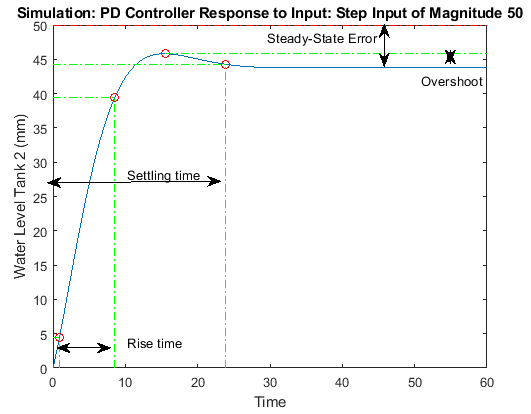

***P Controller:***

**Settling time **($t_{s,1\%}$)**:**

Find the time and the value of the response at settling time (**hint**: you can directly extract the settling time from the *'*`simulation_p_controller_response_info`*'* struct, but since we have discrete timestamps in 1 second intervals, you will need to use the '`interp1`' function to find the value of the response at this exact time): 

Students are required to input below:

simulation_p_controller_settle_time = 0;
simulation_p_controller_settle_value = 0;

**Steady-state value **($h_2,ss$)**:**

Find the steady-state value of the response (**hint**: look at the value of the *'*`simulation_ p_controller_step_value`*'* variable as time tends to the end of the simulation. You can extract this value by addressing the final index of the array in which the data is contained: i.e. array(end)). Extract the time stamp also, which will be used to position the annotations. 

Students are required to input below:

simulation_p_controller_h2ss_time = 0;
simulation_p_controller_h2ss_value = 0;

**Rise time **($t_r$)**:**

The rise time is defined as the time taken by a signal to change from a specified low value to a specified high value. These percentages are commonly the 10% and 90% (or equivalently 0.1 and 0.9) of the output step height. Use the variable* '*`simulation_p_controller_h2ss_value`*'* to calculate the upper and lower response values:

Students are required to input below:

simulation_p_controller_perc_10_value = 0;
simulation_p_controller_perc_90_value = 0;

Use the '`interp1' `function to find the times where the response first reaches the values calculated above:

Students are required to input below:

simulation_p_controller_perc_10_time = 0;
simulation_p_controller_perc_90_time = 0;

**Overshoot **($M_p$)**:**

Inspect the `simulation_p_controller_response_info` struct and you should be able to easily pull out the peak value and peak time. **Hint: **You shouldn't need to use the `interp1` function here, since all the information you need is contained within the struct.

Students are required to input below:

simulation_p_controller_peak_time = 0;
simulation_p_controller_peak_value = 0;

**Plotting:**

Do not change the lines below:

figure(figure_p_sim);
hold on

% Settling Time
plot(simulation_p_controller_settle_time,simulation_p_controller_settle_value,'ro'); % Plot settling time point marker with a red circle
% Plot chart lines to settling point
plot([0 simulation_p_controller_settle_time],[simulation_p_controller_settle_value simulation_p_controller_settle_value],'g-.');
plot([simulation_p_controller_settle_time simulation_p_controller_settle_time],[0 simulation_p_controller_settle_value],'g-.');

% Steady-state Value

% Rise Time
plot(simulation_p_controller_perc_10_time,simulation_p_controller_perc_10_value,'ro'); % Plot 10% rise time point with a red circle
% Plot chart lines to 10% rise time point
plot([0 simulation_p_controller_perc_10_time],[simulation_p_controller_perc_10_value simulation_p_controller_perc_10_value],'g-.');
plot([simulation_p_controller_perc_10_time simulation_p_controller_perc_10_time],[0 simulation_p_controller_perc_10_value],'g-.');

plot(simulation_p_controller_perc_90_time,simulation_p_controller_perc_90_value,'ro'); % Plot 90% rise time point with a red circle
% Plot chart lines to 10% rise time point
plot([0 simulation_p_controller_perc_90_time],[simulation_p_controller_perc_90_value simulation_p_controller_perc_90_value],'g-.');
plot([simulation_p_controller_perc_90_time simulation_p_controller_perc_90_time],[0 simulation_p_controller_perc_90_value],'g-.');

% Overshoot
% peak value:
plot(simulation_p_controller_peak_time,simulation_p_controller_peak_value,'ro'); % Plot peak time point with a red circle
plot([simulation_p_controller_peak_time simulation_p_controller_h2ss_time],[simulation_p_controller_peak_value simulation_p_controller_peak_value],'g-.'); % Plot chart lines to peak point

% Step input magnitude
plot([0 simulation_time_stamps(end)],[h2_ref h2_ref],'r-.');

hold off

Click on the figure, which should bring up a FIGURE tab at the top of the screen:

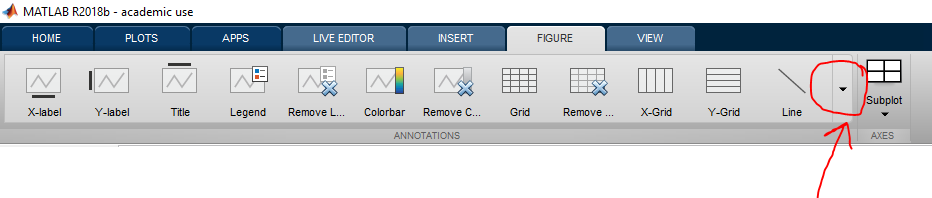

Click on the '**show more**' arrow circled above and inset some double arrow annotations to the relevant parts of the plot to show rise time, settling time etc. Copy the code that is generated below the figure (it should look something like the lines below which use the `annotation `function) and paste it below in the relevant positions. 

Students are required to input below:

% paste the annotations code, replacing the following lines:

% Settling time annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Rise time annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Overshoot annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Steady-state error annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

Add some text labels to the plots to show what the arrow annotations correspond to (you'll have to adjust the location of these by changing the x and y coordinates (`xPos` and `yPos`) located in the matrix [`xPos yPos xBoxSize yBoxSize`]):

Students are required to input below:

annotation('textbox', [0.25 0.1 0.1 0.1], 'String', 'Rise time', 'LineStyle','none')
annotation('textbox', [0.35 0.3 0.1 0.1], 'String', 'Settling time', 'LineStyle','none')
annotation('textbox', [0.45 0.5 0.1 0.1], 'String', 'Overshoot', 'LineStyle','none')
annotation('textbox', [0.55 0.7 0.1 0.1], 'String', 'Steady-State Error', 'LineStyle','none')

***PD Controller:***

As you did with the P controller, populate the variables below which dictate the positions of the plot annotations.

**Settling time **($t_{s,1\%}$)**:**

Students are required to input below:

simulation_pd_controller_settle_time = 0;
simulation_pd_controller_settle_value = 0;

**Steady-state value **($h_2,ss$)**:**

Students are required to input below:

simulation_pd_controller_h2ss_time = 0;
simulation_pd_controller_h2ss_value = 0;

**Rise time **($t_r$)**:**

Students are required to input below:

simulation_pd_controller_perc_10_value = 0;
simulation_pd_controller_perc_90_value = 0;

simulation_pd_controller_perc_10_time = 0;
simulation_pd_controller_perc_90_time = 0;

**Overshoot **($M_p$)**:**

Students are required to input below:

simulation_pd_controller_peak_time = 0;
simulation_pd_controller_peak_value= 0;

**Plotting:**

Do not change the lines below:

figure(figure_pd_sim)
hold on

% Settling Time
plot(simulation_pd_controller_settle_time,simulation_pd_controller_settle_value,'ro'); % Plot settling time point marker with a red circle
% Plot chart lines to settling point:
plot([0 simulation_pd_controller_settle_time],[simulation_pd_controller_settle_value simulation_pd_controller_settle_value],'g-.');
plot([simulation_pd_controller_settle_time simulation_pd_controller_settle_time],[0 simulation_pd_controller_settle_value],'g-.');

% Steady-state Value

% Rise Time
plot(simulation_pd_controller_perc_10_time,simulation_pd_controller_perc_10_value,'ro'); % Plot 10% rise time point with a red circle
% Plot chart lines to 10% rise time point
plot([0 simulation_pd_controller_perc_10_time],[simulation_pd_controller_perc_10_value simulation_pd_controller_perc_10_value],'g-.');
plot([simulation_pd_controller_perc_10_time simulation_pd_controller_perc_10_time],[0 simulation_pd_controller_perc_10_value],'g-.');

plot(simulation_pd_controller_perc_90_time,simulation_pd_controller_perc_90_value,'ro'); % Plot 90% rise time point with a red circle
% Plot chart lines to 10% rise time point
plot([0 simulation_pd_controller_perc_90_time],[simulation_pd_controller_perc_90_value simulation_pd_controller_perc_90_value],'g-.');
plot([simulation_pd_controller_perc_90_time simulation_pd_controller_perc_90_time],[0 simulation_pd_controller_perc_90_value],'g-.');

% Overshoot
% peak value:
plot(simulation_pd_controller_peak_time,simulation_pd_controller_peak_value,'ro'); % Plot peak time point with a red circle
plot([simulation_pd_controller_peak_time simulation_pd_controller_h2ss_time],[simulation_pd_controller_peak_value simulation_pd_controller_peak_value],'g-.'); % Plot chart lines to peak point

% Step input magnitude
plot([0 simulation_time_stamps(end)],[h2_ref h2_ref],'r-.');

hold off

As you did with the P controller, click on the figure and manually add some double arrow annotations to the relevant parts of the plot to show rise time, settling time etc. 

Students are required to input below:

% paste the annotations code, replacing the following lines:

% Settling time annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Rise time annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Overshoot annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

% Steady-state error annotations:
annotation('doublearrow',[0.1473 0.2151],[0.1421 0.1421])

Add some text labels to the plots to show what the arrow annotations correspond to (you'll have to adjust the location of these by changing the x and y coordinates (`xPos` and `yPos`) located in the matrix [`xPos yPos xBoxSize yBoxSize`]):

Students are required to input below:

annotation('textbox', [0.25 0.1 0.1 0.1], 'String', 'Rise time', 'LineStyle','none')
annotation('textbox', [0.35 0.3 0.1 0.1], 'String', 'Settling time', 'LineStyle','none')
annotation('textbox', [0.45 0.5 0.1 0.1], 'String', 'Overshoot', 'LineStyle','none')
annotation('textbox', [0.55 0.7 0.1 0.1], 'String', 'Steady-State Error', 'LineStyle','none')

## **Tuning the controller gains to achieve more accuracy**

**Marks breakdown [3 marks]:**

- A systematic method to tune the controllers if needed

- graphs showing tuned step responses for the tuned controllers.+ proper annotations

Perform some analysis on the results observed and think about the following questions (you can refer to the answers in the discussion section):

- **P Controller:** was the *steady-state error* spec met? (within 5% tolerance band)

- **PD Controller:** were the *rise time* and *settling time specs* met? (within 5% tolerance band)

- If the answer is no for either of these questions, what might be the reason for this? 

- What can you do to try and meet the specs? **Hint: **A good approach is to tune the controller gains. Provide calculations and justifications as necessary.

If you need to tune the controller gains, provide a systematic method and results below. Two approaches are suggested: either use a** coded trial and error **or try to understand deeply the role of each controller gain. You can **plot some graphs for different values of controller gains**. For instance, if the PD controller requires tuning, keep $K_d$ constant while changing $K_p$ in a reasonable span. To simulate the tuned controller and demonstrate the results, you will need to write the code yourself (or copy and paste from above, changing **ALL COPIED **variable names to something sensible with a prefix of 'tuned' like '`p_controller_tf_tuned = tf(kp_p_controller_tuned,1);`'  etc. Do not forget to include the **annotations** as before.

Students are required to input below:

% coded tuning strategy

% tuned P controller response (if needed):
%figure_p_Sim_response_tuned = figure();
%plot(0,0) % plot the data using the variables above
%title('Simulation: Tuned P Controller Step Response')
%xlabel('')
%ylabel('')

% tuned PD controller response (if needed):
%figure_pd_Sim_response_tuned = figure();
%plot(0,0) % plot the data using the variables above
%title('Simulation: Tuned PD Controller Step Response')
%xlabel('')
%ylabel('')

# Task 5 [5 marks]

## Discussion and Reflection

**Marks breakdown [5 marks]:**

Brief discussion on the results covering the following points:

- Having completed the theoretical calculations and simulations, what have you found? 

- Comment on the validity of the data and the methods used. What could be improved?

- Did you have to tune the gains of the controller/s to achieve the desired rise time and settling time? If so, why? Provide graphs to reference to back up your arguments. 

- What are the advantages and disadvantages of each controller? 

- What type of controller would you recommend and why? 

Students are required to input below:

discussion = 'discussion here';

## *For Marking*

Do not change the lines below:

disp(discussion)

Export variables from workspace for automatic marking via MATLAB:

clear figure_p_sim
clear figure_pd_sim
saveFileName = strcat('MinorProject_2_', student_id, '_variables.mat');
save(saveFileName)
